# Programmierblatt 2

#### Finite Differenzen, Laplace und Poisson Gleichung

Bearbeitende Studierende:

Jonathan Schnitzler    Matr. - Nr: 3465192

Matthias Gültig           Matr. - Nr: 3469020

Anmerkungen: Alle Aufgaben wurden bereits mit der freiwilligen aber sinnvollen Forderung nach Erweiterung bzw. Generalisierbarkeit implementiert

##  Aufgabe 1 (FD-Gitter)

In dieser Aufgabe wird das Gitter $\Omega =\left({\left(0,3\right)}^2 \backslash \left(\left\lbrack 2,3\right)\times \left(0,1\rbrack \right.\right)\right)\backslash \left(\left(0,1\right\rbrack \times \;\left\lbrack 2,3\right)\right)$

Die Grundlegende Idee ist die kleinstmögliche Basis $\Omega {\;}_R$ zu schaffen, sodass $\bar{\Omega {\;}_h \;} \subset \;\Omega {\;}_R$ und ein rechteckiges Würfelgitter ist. Dann reicht es aus diesem allgemeinen Gitter kleinere Rechtecke "auszuschneiden", und man kann jedes beliebige gewünschte Gebiet erhalten.

h = 0.2;


%Generating square base (0,3)^2
omega.o = [0,0];
omega.x = 3;
omega.y = 3;
omega.h = h;

omega = genRectMesh2D(omega);


%Plotting in little animation, how the index are counted
% animate(omega);

%Creating upper left and lowwer right square

%Top left
tlSquare.o = [0, 2];
tlSquare.x = 1;
tlSquare.y = 1;
tlSquare.h = h;

tlSquare = genRectMesh2D(tlSquare);

%Lower right
drSquare.o = [2, 0];
drSquare.x = 1;
drSquare.y = 1;
drSquare.h = h;

drSquare = genRectMesh2D(drSquare);

%Subtracting the Geometry from omega

omega = meshSubtract(omega,tlSquare, "ctl");
omega = meshSubtract(omega,drSquare, "cdr");

% animate(omega);



%Testing some shit
h = [1, 0.5, 0.25, 0.125 0.1, 0.05, 0.02]

h =     1.0000    0.5000    0.2500    0.1250    0.1000    0.0500    0.0200


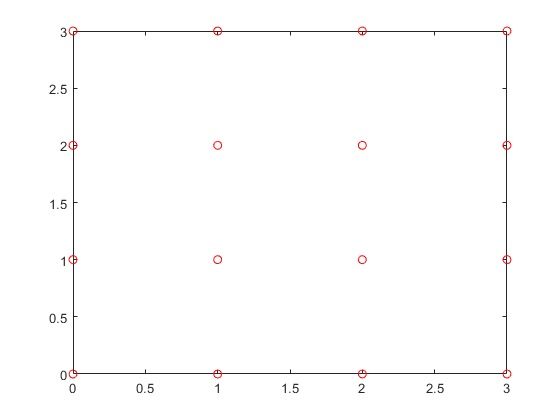

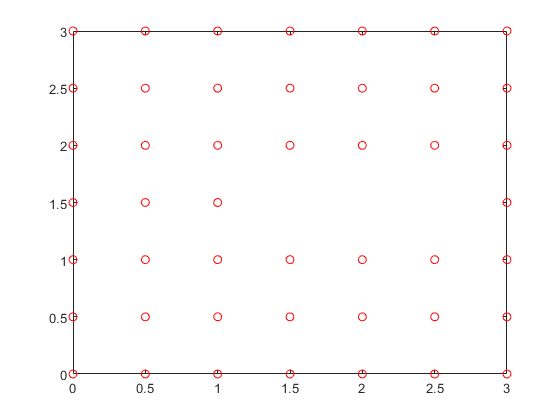

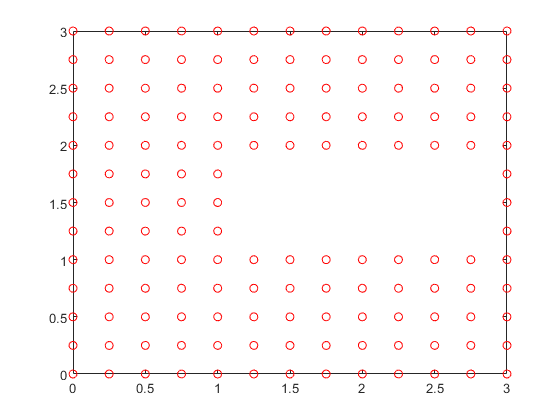

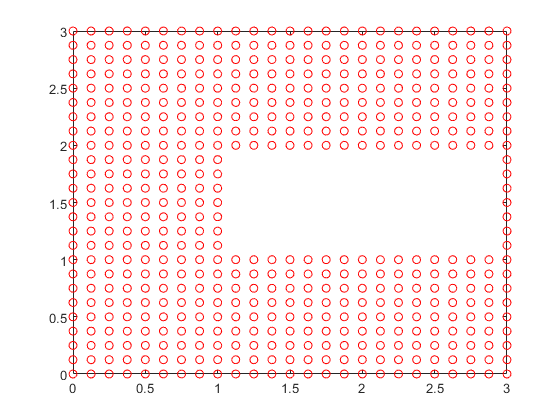

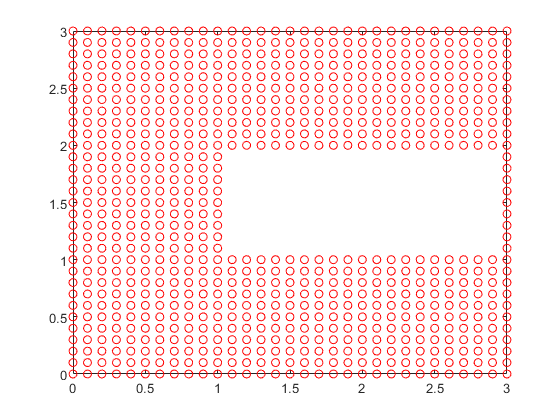

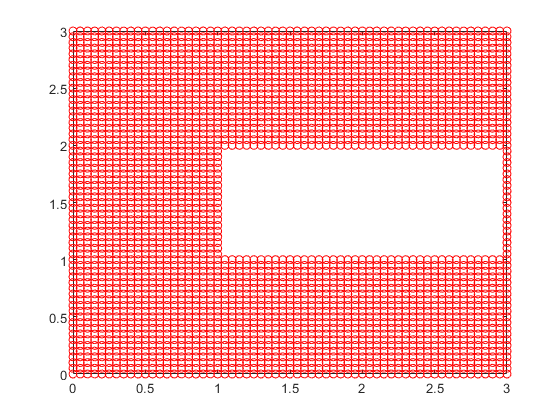

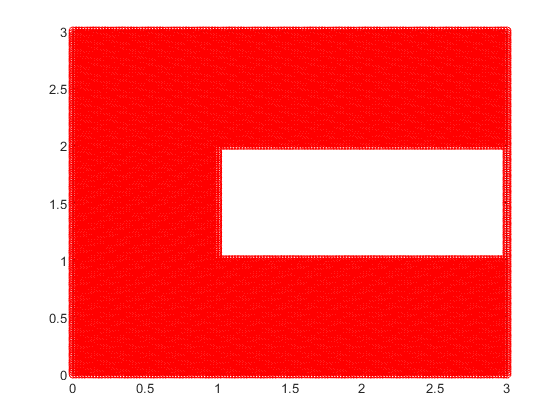

t = zeros(numel(h),1);
for k = 1:numel(h)
    tic
omeg.o = [0,0];
omeg.x = 3;
omeg.y = 3;
omeg.h = h(k);
O1 = genRectMesh2D(omeg);
omeg.x = 2;
omeg.y = 1;
omeg.o = [1, 1];
O2 = genRectMesh2D(omeg);

O = meshSubtract(O1,O2,"i");
O = O.pointMat;
figure
plot(O(:,1), O(:,2),'ro');
t(k) = toc;
end

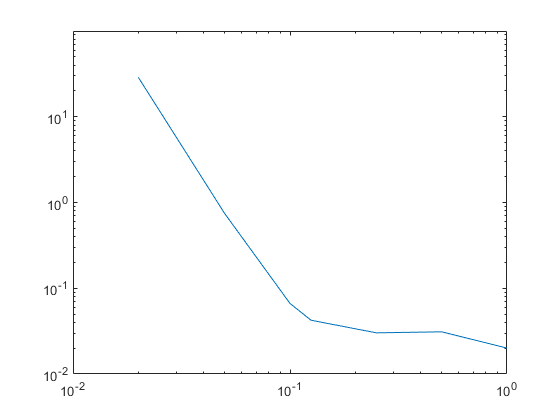

loglog(h,t)

function assemble(omega, h)

end

function OmegaHBar = genRectMesh2D(omeg)
%Input is a struct specifying the origin the X-Length, the Y-Length and the
%Meshsize h
    if mod(omeg.x,omeg.h) ~= 0 || mod(omeg.y,omeg.h) ~= 0
        error("X-Length or Y-Length are not applicable with the Meshsize of h");
    end
    
    nX = round(omeg.x/omeg.h);
    nY = round(omeg.y/omeg.h);
    N = (nX+1).*(nY+1);
    OmegaHBar = omeg;
    OmegaHBar.pointMat = zeros(N,2);
    for kY = 0:nY
        for kX = 0:nX
            OmegaHBar.pointMat(kY*(nX+1) + (kX + 1),:) = [omeg.o(1) + kX *omeg.h, omeg.o(2) + omeg.y - kY * omeg.h];
        end
    end
end

function OmegaHBar = meshSubtract(Omega, subOmega, edge)
%Subtracts a rectangular mesh from an arbitrary cubic Mesh while keeping the
%edges
if subOmega.h ~= Omega.h
    error("Meshsizes h are different");
end
h = subOmega.h;

if mod(subOmega.o(1)-Omega.o(1), h) ~= 0 || mod(subOmega.o(2)-Omega.o(2), h) ~= 0
    error("Origins are not a multiple of h appart from each other")
end


innerPoints = edgeCase(edge, subOmega, h);

innerPoints = genRectMesh2D(innerPoints);



OmegaHBar = Omega; %Take old settings even tough it may have been altered
OmegaHBar.pointMat = meshSubtractWithEdge(Omega.pointMat,innerPoints.pointMat);


end

function Omega = meshSubtractWithEdge(pM, pMSub)
%Input is the point Matrix of a area and an area you want to subtract it
%from - output is the point Matrix of pM without pMSub
%Could be implemented faster
isIn = zeros(size(pM,1),1);
for k1 = 1:size(pM,1)
    for k2 = 1:size(pMSub,1)
        if equalEps(pM(k1,:),pMSub(k2,:))
            isIn(k1) = 1;
            break;
        end
    end
end
Omega = pM(~logical(isIn),:);
end


function equalEps = equalEps(x, y)
%Basicly a more robust "=="
    if norm(x-y) < 1e4*eps(min(norm(x),norm(y)))
        equalEps = true;
    else
        equalEps = false;
    end
end

function animate(omega)
%Animates the mesh given by the struct animate
figure;
plot(omega.o(1),omega.o(2),'ro');
xlim([omega.o(1),omega.o(1)+omega.x])
ylim([omega.o(2),omega.o(2)+omega.y])
hold on
n = size(omega.pointMat,1);
for k=1:n
    color = ones(3,1)*(k/n);
    plot(omega.pointMat(k,1),omega.pointMat(k,2),'Color',color,"Marker",'o')
    
    drawnow
    pause(1/n)
end
hold off
end


function innerPoints = edgeCase(edge, subOmega, h)
%Check which border to subtract and which to keep
%Inner
if edge == "i"
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [h, h];
    
    %Single
elseif edge == "st" %single top
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "sl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [0, h];
    
elseif edge == "sr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "sd"
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, 0];
    %Double  
elseif edge == "dt" % ||    ||
    innerPoints.x = subOmega.x - 2*h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [h, 0];
    
    
elseif edge == "dd" % __--
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - 2*h;
    innerPoints.o = subOmega.o + [0, h];
    
    %Corner (Corner indicates where the boarder is removed)
    %only the possition of innerPoints.o changes
elseif edge == "ctl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, h];
    
elseif edge == "ctr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, h];
    
elseif edge == "cdl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "cdr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [h, 0];
    
    
    %Tube Position where border should remain
elseif edge == "tt"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "tl"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [h, 0];
    
elseif edge == "tr"
    innerPoints.x = subOmega.x - h;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [0, 0];
    
elseif edge == "td"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y - h;
    innerPoints.o = subOmega.o + [0, h];
    
    %All
    endif edge == "all"
    innerPoints.x = subOmega.x;
    innerPoints.y = subOmega.y;
    innerPoints.o = subOmega.o + [0, 0];
end

innerPoints.h = h;
end